% Natural temperature processing
close all
clc
clear
warning off
format long

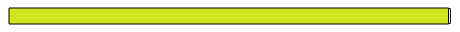

% load data (#2 20220719)
[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        REV_ST(i+1,j)=str2double(cell2mat(dataValue(4)));
        REV_AST(i+1,j)=str2double(cell2mat(dataValue(5)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(6)));
    end
    progressbar(j/n)
end

RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime;
DTS.RT=RT;
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF;
DTS.ST=ST;
DTS.AST=AST;
DTS.REV_ST=REV_ST;
DTS.REV_AST=REV_AST;
DTS.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

% time information
Info.start_test = '2022/07/19  14:30:00'; % apply the test
Info.end_test = '2022/07/19  17:30:00'; % finish the test or start the heating
clearvars -except Info DTS;

% Extract the data in time
p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

testProcessTime.timeseconds = time_seconds;
testProcessTime.temperature = temperature_processing;
clearvars -except testProcessTime Info DTS;

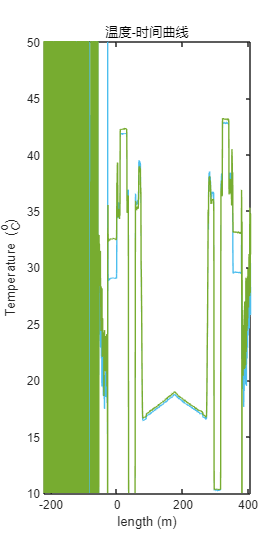

% Check the length
figure(1)
plot(DTS.LAF,testProcessTime.temperature(:,1))
hold on
plot(DTS.LAF,testProcessTime.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');

% 202207Borehole [75.63,175.53,275.431]

% Extract the data in length
testProcessTimeDepth.timeseconds = testProcessTime.timeseconds;
q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=75.63 && DTS.LAF(k,1)<=175.53
        q = q+1;
        testProcessTimeDepth.depth(q,1) = DTS.LAF(k,1)-75.63;
        testProcessTimeDepth.temperature(q,:) = testProcessTime.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=175.53 && DTS.LAF(k,1)<=275.431
        q = q+1;
        testProcessTimeDepth.anti_depth(q,1) = 2275.431-DTS.LAF(k,1);
        testProcessTimeDepth.anti_temperature(q,:) = testProcessTime.temperature(k,:);
    end
end

testProcessTimeDepth.anti_depth = flip(testProcessTimeDepth.anti_depth);
testProcessTimeDepth.anti_temperature = flip(testProcessTimeDepth.anti_temperature);
clear k q

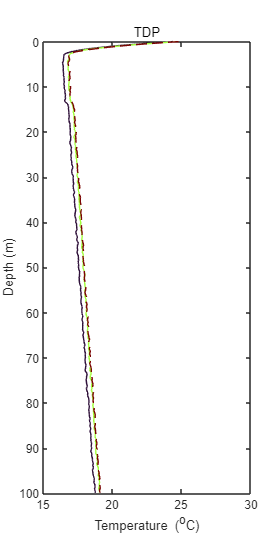

% temperature-depth
figure(1)
color_line = turbo(3);
plot(testProcessTimeDepth.temperature(:,1),testProcessTimeDepth.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(testProcessTimeDepth.temperature(:,86),testProcessTimeDepth.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(testProcessTimeDepth.temperature(:,end),testProcessTimeDepth.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off 
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");

set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

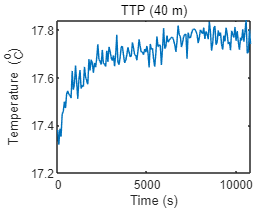

% temperature-time
figure(2)
plot(testProcessTime.timeseconds,testProcessTimeDepth.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');

% save the processed data
save data_jintan_02_20220719_process_2022091600.mat

% data transform
load jintan.mat jintan
jintan.bore2.depth20220719 = testProcessTimeDepth.depth;
jintan.bore2.temperature202207191600 = mean(testProcessTimeDepth.temperature(:,1:end),2);
save jintan.mat jintan

% next one
clear 
clc

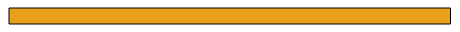

% load data (#2 202109)
[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        REV_ST(i+1,j)=str2double(cell2mat(dataValue(4)));
        REV_AST(i+1,j)=str2double(cell2mat(dataValue(5)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(6)));
    end
    progressbar(j/n)
end

RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime;
DTS.RT=RT;
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF;
DTS.ST=ST;
DTS.AST=AST;
DTS.REV_ST=REV_ST;
DTS.REV_AST=REV_AST;
DTS.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

% time information
Info.start_test = '2021/09/19  13:30:00'; % apply the test
Info.end_test = '2021/09/19  17:00:00'; % finish the test or start the heating
clearvars -except Info DTS;

% Extract the data in time
p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

testProcessTime.timeseconds = time_seconds;
testProcessTime.temperature = temperature_processing;
clearvars -except testProcessTime Info DTS;

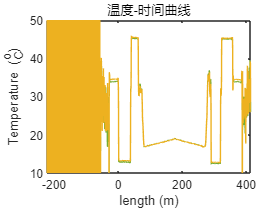

% Check the length
figure(1)
plot(DTS.LAF,testProcessTime.temperature(:,1))
hold on
plot(DTS.LAF,testProcessTime.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');

% 202109Borehole [76.349,176.249,276.149]

% Extract the data in length
testProcessTimeDepth.timeseconds = testProcessTime.timeseconds;
q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=76.349 && DTS.LAF(k,1)<=176.249
        q = q+1;
        testProcessTimeDepth.depth(q,1) = DTS.LAF(k,1)-76.349;
        testProcessTimeDepth.temperature(q,:) = testProcessTime.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=176.249 && DTS.LAF(k,1)<=276.149
        q = q+1;
        testProcessTimeDepth.anti_depth(q,1) = 276.149-DTS.LAF(k,1);
        testProcessTimeDepth.anti_temperature(q,:) = testProcessTime.temperature(k,:);
    end
end

testProcessTimeDepth.anti_depth = flip(testProcessTimeDepth.anti_depth);
testProcessTimeDepth.anti_temperature = flip(testProcessTimeDepth.anti_temperature);
clear k q

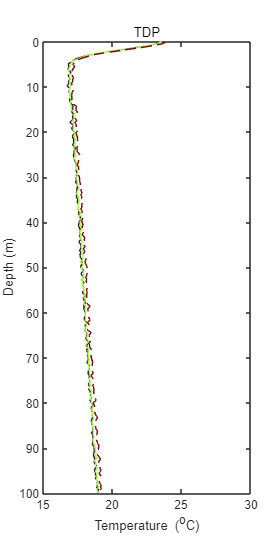

% temperature-depth
figure(1)
color_line = turbo(3);
plot(testProcessTimeDepth.temperature(:,1),testProcessTimeDepth.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(testProcessTimeDepth.temperature(:,289),testProcessTimeDepth.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(testProcessTimeDepth.temperature(:,end),testProcessTimeDepth.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);

clear color_line

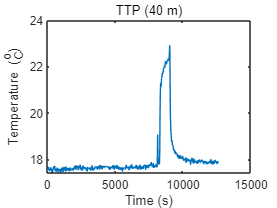

% temperature-time
figure(2)
plot(testProcessTime.timeseconds,testProcessTimeDepth.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');

% select the undistributed data, before 8038 s

% save the processed data
save data_jintan_02_20210919_process_202209152350.mat

% data transform
load jintan.mat jintan
jintan.bore2.depth20210919 = testProcessTimeDepth.depth;
jintan.bore2.temperature202109191415 = mean(testProcessTimeDepth.temperature(:,1:369),2);
save jintan.mat jintan

% next one
clear
clc

% load data (#4 20220718)
[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        REV_ST(i+1,j)=str2double(cell2mat(dataValue(4)));
        REV_AST(i+1,j)=str2double(cell2mat(dataValue(5)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(6)));
    end
    progressbar(j/n)
end
RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime;
DTS.RT=RT;
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF;
DTS.ST=ST;
DTS.AST=AST;
DTS.REV_ST=REV_ST;
DTS.REV_AST=REV_AST;
DTS.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

% time information
Info.start_test = '2022/07/18  18:30:00'; % apply the test
Info.end_test = '2022/07/18  19:30:00'; % finish the test or start the heating
clearvars -except Info DTS;

% Extract the data in time
p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

testProcessTime.timeseconds = time_seconds;
testProcessTime.temperature = temperature_processing;
clearvars -except testProcessTime Info DTS;

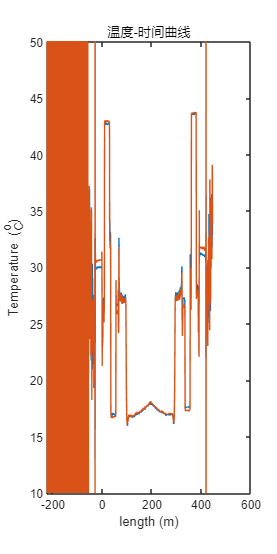

% Check the length
figure(1)
plot(DTS.LAF,testProcessTime.temperature(:,1))
hold on
plot(DTS.LAF,testProcessTime.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');


% 202207Borehole [95.712,195.612,295.513]

% Extract the data in length
testProcessTimeDepth.timeseconds = testProcessTime.timeseconds;
q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=95.712 && DTS.LAF(k,1)<=195.612
        q = q+1;
        testProcessTimeDepth.depth(q,1) = DTS.LAF(k,1)-95.712;
        testProcessTimeDepth.temperature(q,:) = testProcessTime.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=195.612 && DTS.LAF(k,1)<=295.513
        q = q+1;
        testProcessTimeDepth.anti_depth(q,1) = 295.513-DTS.LAF(k,1);
        testProcessTimeDepth.anti_temperature(q,:) = testProcessTime.temperature(k,:);
    end
end

testProcessTimeDepth.anti_depth = flip(testProcessTimeDepth.anti_depth);
testProcessTimeDepth.anti_temperature = flip(testProcessTimeDepth.anti_temperature);
clear k q

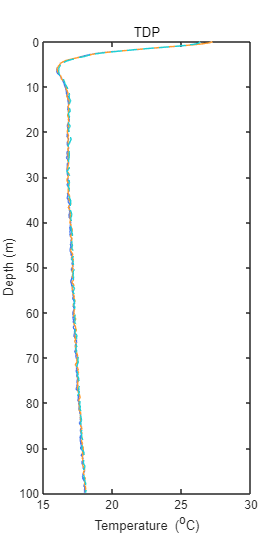

% temperature-depth
figure(1)
color_line = turbo(8);
plot(testProcessTimeDepth.temperature(:,1),testProcessTimeDepth.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on 
plot(testProcessTimeDepth.temperature(:,11),testProcessTimeDepth.depth,"Color",color_line(6,:),'LineWidth',0.75)
hold on
plot(testProcessTimeDepth.temperature(:,end),testProcessTimeDepth.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off 
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");

set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

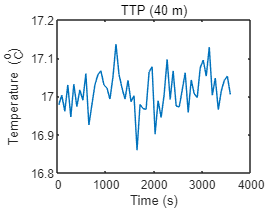

% temperature-time
figure(2)
plot(testProcessTime.timeseconds,testProcessTimeDepth.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');

% save the processed data
save data_jintan_04_20220718_process_202208311950.mat

% data transform
load jintan.mat jintan
jintan.bore4.depth20220718 = testProcessTimeDepth.depth;
jintan.bore4.temperature202207181900 = mean(testProcessTimeDepth.temperature(:,1:end),2);
save jintan.mat jintan

% next one
clear 
clc

% load data (#4 202109)
[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        REV_ST(i+1,j)=str2double(cell2mat(dataValue(4)));
        REV_AST(i+1,j)=str2double(cell2mat(dataValue(5)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(6)));
    end
    progressbar(j/n)
end
RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime;
DTS.RT=RT;
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF;
DTS.ST=ST;
DTS.AST=AST;
DTS.REV_ST=REV_ST;
DTS.REV_AST=REV_AST;
DTS.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

% time information
Info.start_test = '2021/09/18  17:10:00'; % apply the test
Info.end_test = '2021/09/18  18:00:00'; % finish the test or start the heating
clearvars -except Info DTS;

% Extract the data in time
p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

testProcessTime.timeseconds = time_seconds;
testProcessTime.temperature = temperature_processing;
clearvars -except testProcessTime Info DTS;

% Check the length
figure(1)
plot(DTS.LAF,testProcessTime.temperature(:,1))
hold on
plot(DTS.LAF,testProcessTime.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');
% 202109Borehole [76.349,176.249,276.149]  need check!

% Extract the data in length
testProcessTimeDepth.timeseconds = testProcessTime.timeseconds;
q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=76.349 && DTS.LAF(k,1)<=176.249
        q = q+1;
        testProcessTimeDepth.depth(q,1) = DTS.LAF(k,1)-76.349;
        testProcessTimeDepth.temperature(q,:) = testProcessTime.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=176.249 && DTS.LAF(k,1)<=276.149
        q = q+1;
        testProcessTimeDepth.anti_depth(q,1) = 276.149-DTS.LAF(k,1);
        testProcessTimeDepth.anti_temperature(q,:) = testProcessTime.temperature(k,:);
    end
end

testProcessTimeDepth.anti_depth = flip(testProcessTimeDepth.anti_depth);
testProcessTimeDepth.anti_temperature = flip(testProcessTimeDepth.anti_temperature);
clear k q

% temperature-depth
figure(1)
color_line = turbo(3);
plot(testProcessTimeDepth.temperature(:,1),testProcessTimeDepth.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(testProcessTimeDepth.temperature(:,289),testProcessTimeDepth.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(testProcessTimeDepth.temperature(:,end),testProcessTimeDepth.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off 
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

% temperature-time
figure(2)
plot(testProcessTime.timeseconds,testProcessTimeDepth.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');
% select the undistributed data, before 8038 s

% save the processed data
save data_jintan_04_20210918_process_202208312110.mat

% data transform
load jintan.mat jintan
jintan.bore4.depth20210918 = testProcessTimeDepth.depth;
jintan.bore4.temperature202109181930 = mean(testProcessTimeDepth.temperature(:,1:369),2); % need check!
save jintan.mat jintan

% next one
clear
clc

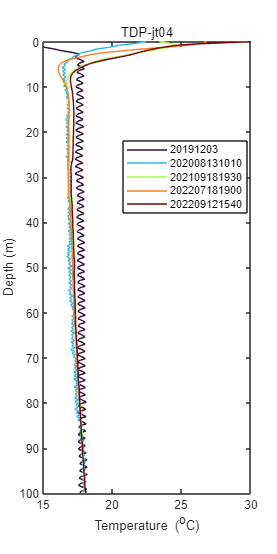

% update
load jintan.mat
figure(3)
color_line = turbo(5);
plot(jintan.bore4.temperature20191203+0.4,jintan.bore4.depth20191203,"Color",color_line(1,:),'LineWidth',0.75)
hold on
plot(jintan.bore4.temperature202008131010,jintan.bore4.depth20200813,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(jintan.bore4.temperature202109181930-0.4,jintan.bore4.depth20210918,"Color",color_line(3,:),'LineWidth',0.75)
hold on
plot(jintan.bore4.temperature202207181900,jintan.bore4.depth20220718,"Color",color_line(4,:),'LineWidth',0.75)
hold on
plot(jintan.bore4.temperature202209121540-0.55,jintan.bore4.depth20220912,"Color",color_line(5,:),'LineWidth',0.75)
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP-jt04')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
legend('20191203','202008131010','202109181930','202207181900','202209121540',location='best')

set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

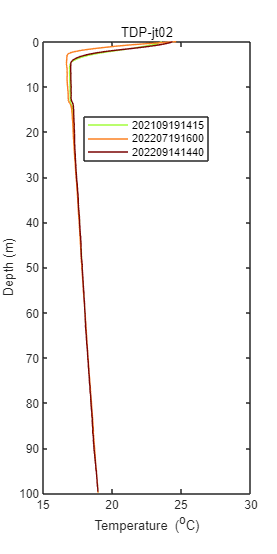

% update
load jintan.mat
figure(4)
color_line = turbo(5);
plot(jintan.bore2.temperature202109191415,jintan.bore2.depth20210919,"Color",color_line(3,:),'LineWidth',0.75)
hold on
plot(jintan.bore2.temperature202207191600-0.1,jintan.bore2.depth20220718,"Color",color_line(4,:),'LineWidth',0.75)
hold on
plot(jintan.bore2.temperature202209141440-0.4,jintan.bore2.depth20220914,"Color",color_line(5,:),'LineWidth',0.75)
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP-jt02')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
legend('202109191415','202207191600','202209141440',location='best')

set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line